clc;
close all;
clear all;


set(groot,'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex');  
set(groot, 'defaultLegendInterpreter','latex');

L = 4;
N = 500;

M = [-5, -7, 6, 8;
     -5,  7,-6, 8];
  
rho = rand(1, L) * 2 - 1;

sigma = randn(2, L)*0.2 + 1;

samples = Samples.empty(L, 0);
all_samples = zeros(2, L*N);
for i = 1:L
    samples(i) = Samples(M(:, i), sigma(:, i), rho(i), N);
    all_samples(:, (i - 1)*N + 1:i*N) = samples(i).samples;
end

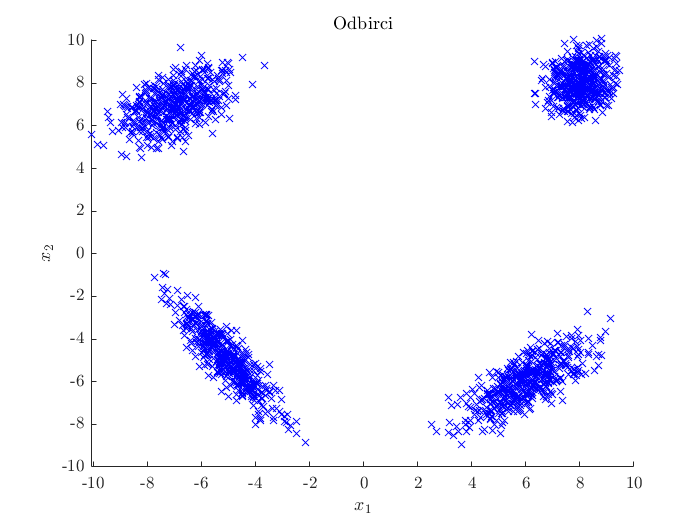

figure
hold on;
for i = 1:L
    samples(i).plot('bx')
end

title("Odbirci")
xlabel("$x_1$")
ylabel("$x_2$")

% % TODO shuffle function
% shuffle(all_samples);
% 
% % TODO Cluster class
% clusters = Cluster.empty(L, 0);
% 
% for j = 1:L
%     clusters(j) = Cluster(all_samples(:, (j - 1)*N + 1:j*N));
% end
%  
% moze i u konstruktoru
% for i = 1:L
%     clusters(i).recalculate_params();
% end
% 
% while true
%     % if break_flag remains true when we process all samples then we will
%     % break
%     break_flag = true;
%     
%     % for each sample sum(Li*Ni)
%     for j = 1:L
%         for i = 1:length(clusters(j).samples) 
%             
%             X = clusters(j).samples(:, i);
%             
%             % calculate the criterium function values for sample X
%             % and all the clusters
%             J_vals = zeros(L, 1);
%             for k = 1:L
%                 J_vals(k) = J(X, clusters(k).P, clusters(k).M, clusters(k).S);
%             end
%             
%             % take the minimum argument
%             [~, arg_minimum] = min(J_vals);
%             
%             % if X is already in the minimum criterium class
%             % do nothing
%             if j == arg_minimum
%                 continue;
%             else
%                 % else remove X from the current cluster
%                 % and insert it into the minimum criterium cluster
%                 clusters(j).pop(i);
%                 clusters(arg_minimum).push(X);
%             end
%             
%         end
%     end
%     
%     % this is the end of one iteration,
%     % recalculate the parameters for each cluster
%     for cnt = 1:L
%         clusters(cnt).recalculate_params();
%     end
%     
%     % TODO insert oscillation check
%     
%     if break_flag
%         break;
%     end
% end
% 
% 